A1

clear;warning off;
f = @(czajnik) 2 * exp(czajnik) + 5 * sin(4 * czajnik);

x7p = linspace(0, 3, 7);
x301p = linspace(0, 3, 301);
y7p = f(x7p);
y301p = f(x301p);
plot(x7p, y7p)
hold on;
plot(x301p, y301p)

A2

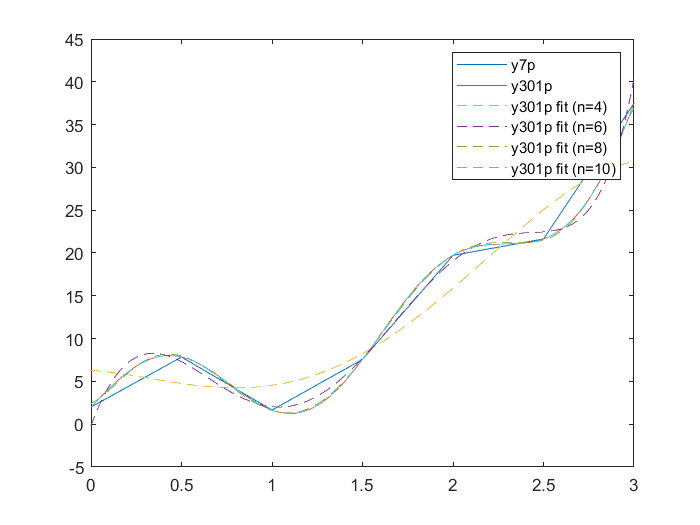

legend_names=["y7p","y301p"];
n=(4:2:10);
for i=1:length(n)
[p, S] = polyfit(x301p, y301p, n(i));
[y301p_fit] = polyval(p, x301p, S);
plot(x301p, y301p_fit, "--")
legend_names(end+1)="y301p fit (n="+string(n(i))+")";
end
legend(legend_names);
hold off;

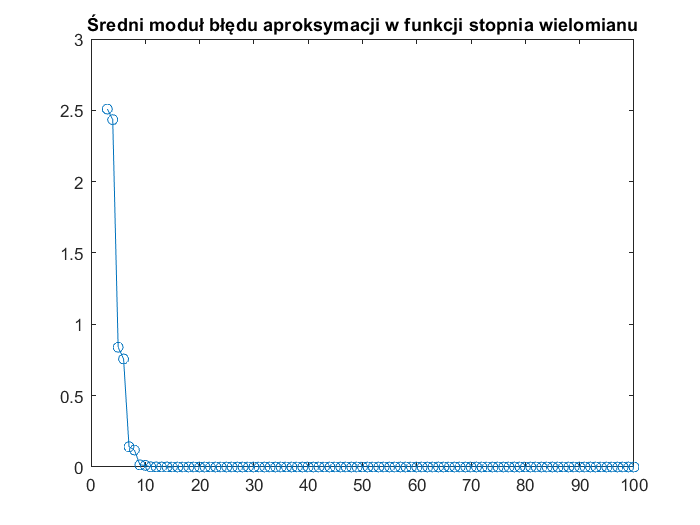


n=[3:100];
smba=zeros(1,length(n));
for i=1:length(n)
    smba(i)=sredniModulBleduAproksymacji(x301p,y301p,n(i));
end
plot(n,smba,'-o')
title("Średni moduł błędu aproksymacji w funkcji stopnia wielomianu")

A3

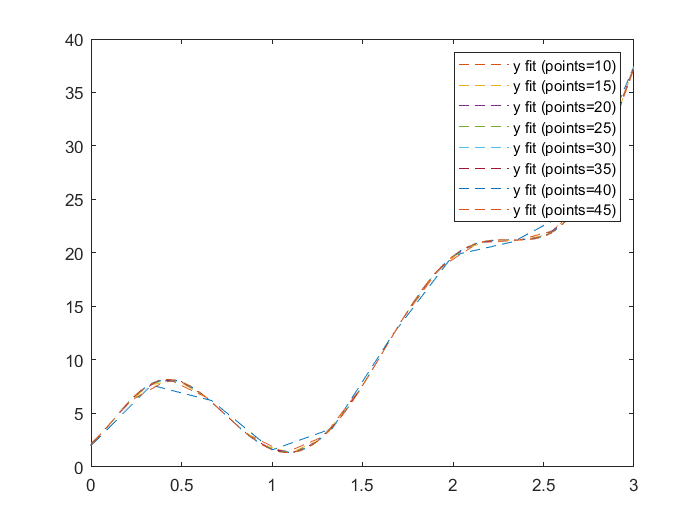

n = (10:5:50);
legend_names=strings;
for i = 1:length(n)
    x = linspace(0, 3, n(i));
    y = f(x);
    [p, S] = polyfit(x, y, 8);
    [y_fit] = polyval(p, x, S);
    plot(x, y_fit, "--")
    legend_names(end + 1) = "y fit (points=" + string(n(i)) + ")";
    hold on;
end

legend(legend_names);
hold off;

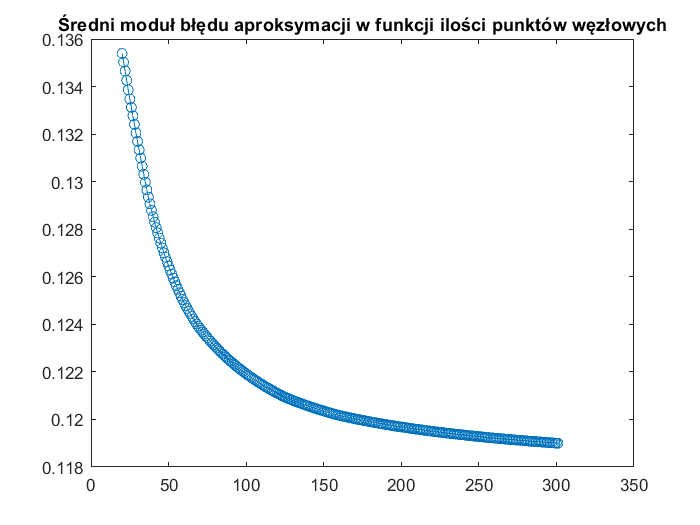


n=[20:301];
smba=zeros(1,length(n));
for i=1:length(n)
    smba2(i)=sredniModulBleduAproksymacji2(f,n(i));
end
plot(n,smba2,'-o')
title("Średni moduł błędu aproksymacji w funkcji ilości punktów węzłowych")